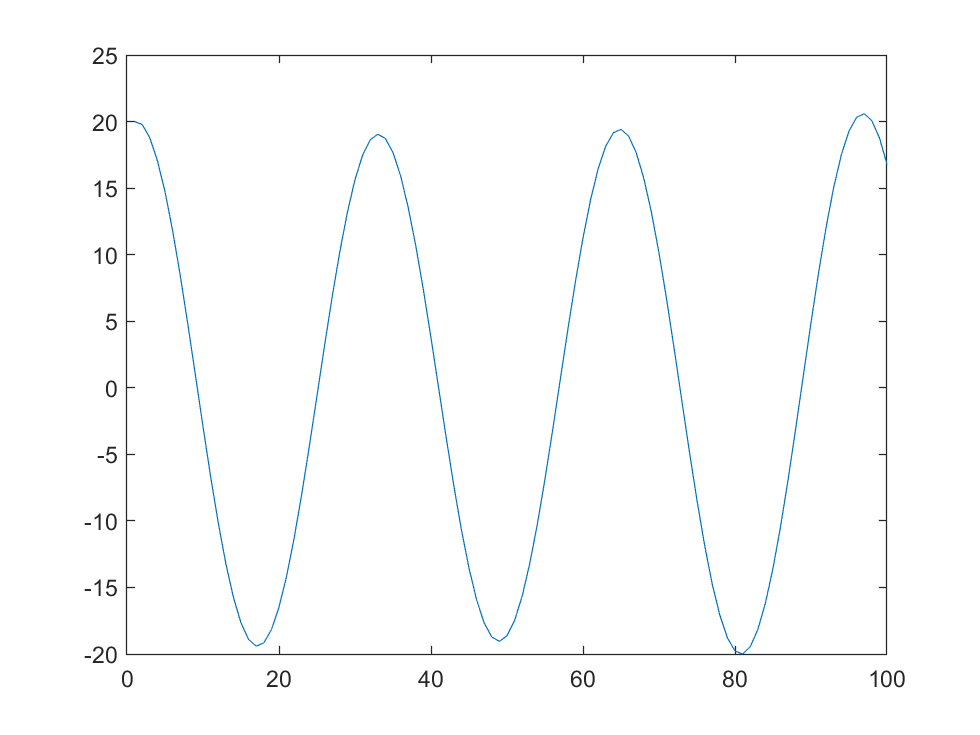

%ECOMMS Lab Project 1 Example 
%Dawson Tocarchick, Kyle Limbaga, Michael Johns
%Rowan University 
%This program generates a 1-second duration  
%Asharp signal (466.16 Hz) with a specified SNR

%Specify SNR 
snr=10; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';

A_c = 20; 
f_m = 200;
f_c = 250;
b = 1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%   Different Waveforms     %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%s = 0.5*sin(2*pi*466.16*t);
%s = A_c*[1+cos(2*pi*f_m*t)].*(cos(2*pi*f_c*t));
s = A_c*cos(2*pi*f_c*t) + b*sin(2*pi*f_m*t);

plot(s);
xlim([0 100]);

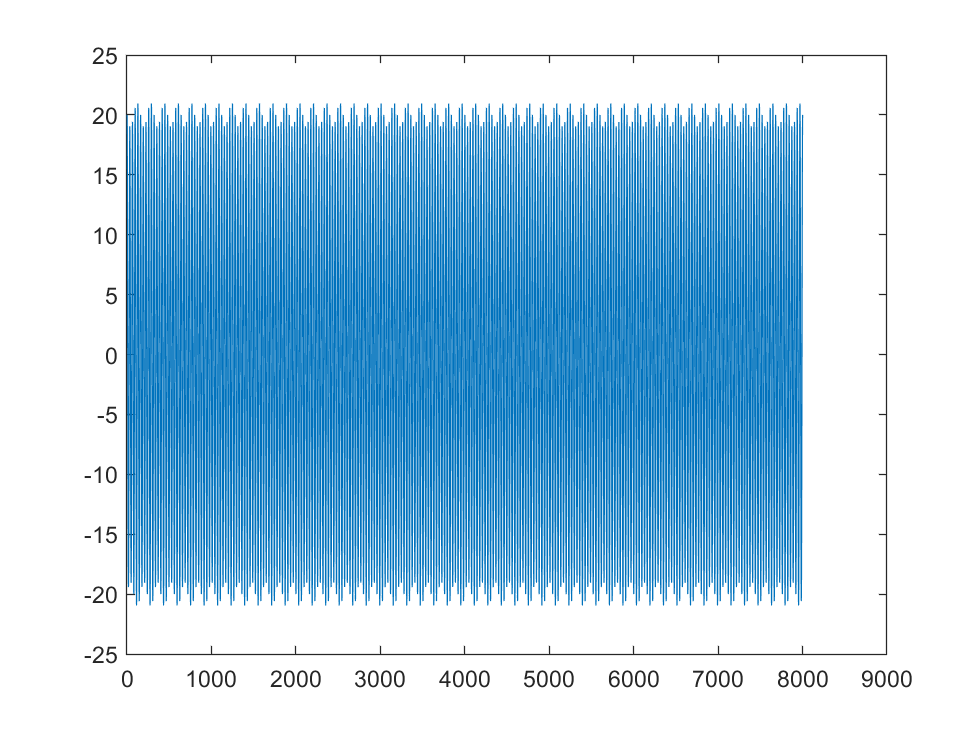


%sound(s); 

%Compute signal variance 
var_s = cov(s);

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); %sound(n);

%Add signal to noise and generate message 
m=s+n; %sound(m); 

plot(s);

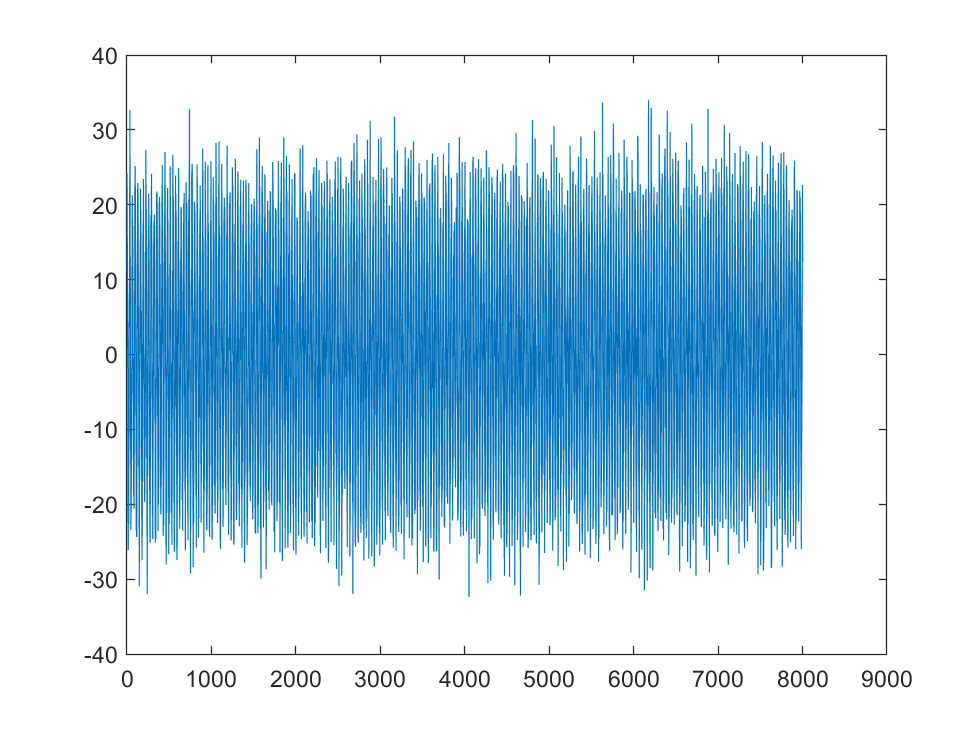

plot(m);

# part 2 Mike J:

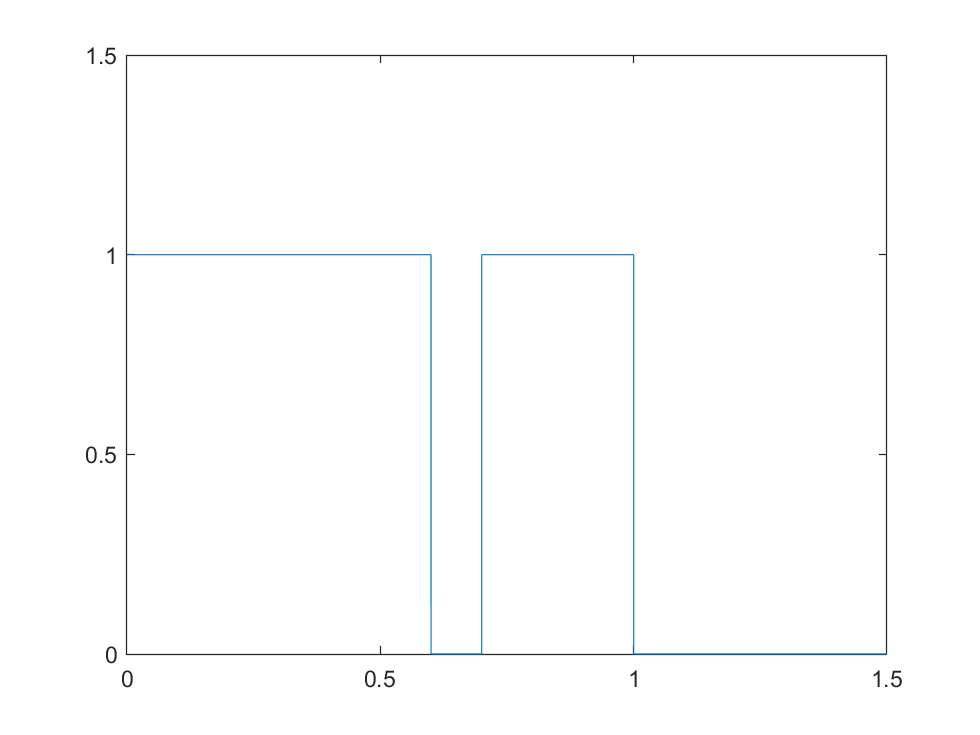

% syms x;
% fplot(heaviside([x-1;x]), [-2,2])

syms y(x)
y(x) = rectangularPulse(0,0.6,x)+rectangularPulse(0.7,1,x);

figure(1);
fplot(y);
axis([0 1.5 0 1.5]);

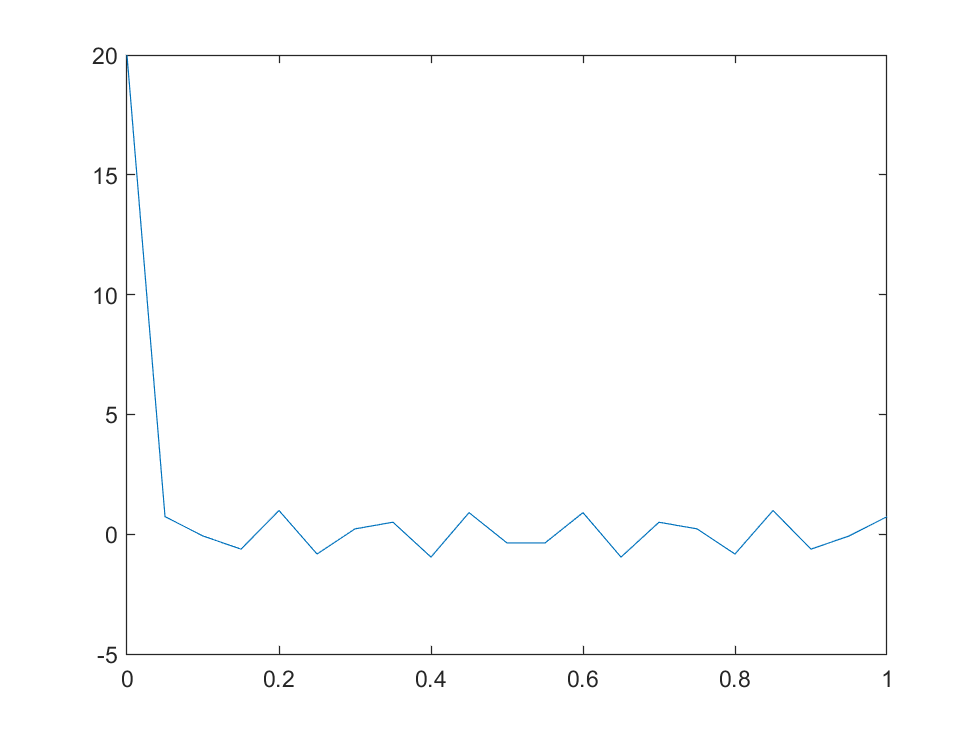


figure(2);
plot([0:0.05:1],fft(double(y([0:0.05:1]))));

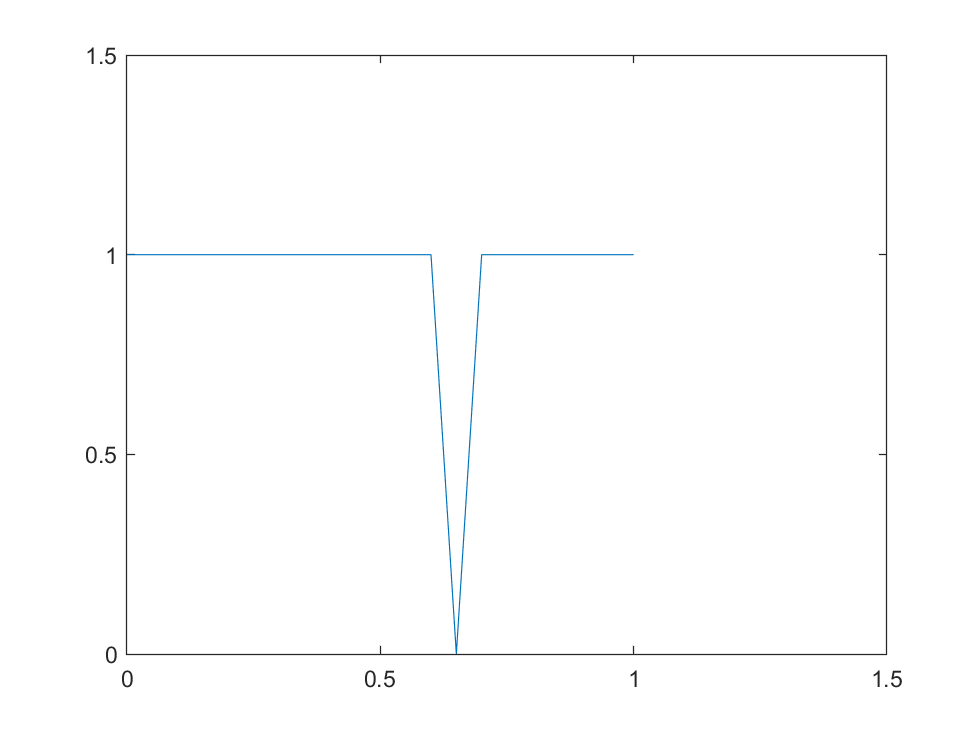


figure(3);
plot([0:0.05:1],ifft(fft(double(y([0:0.05:1])))));
axis([0 1.5 0 1.5]);

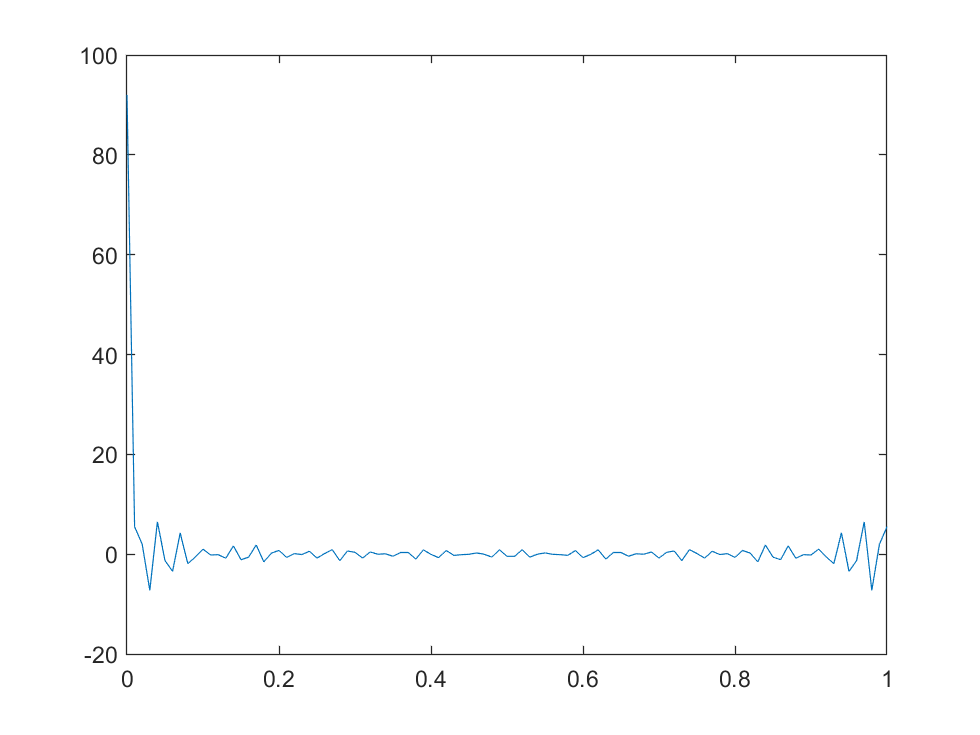


figure(4);
plot([0:0.01:1],fft(double(y([0:0.01:1]))));

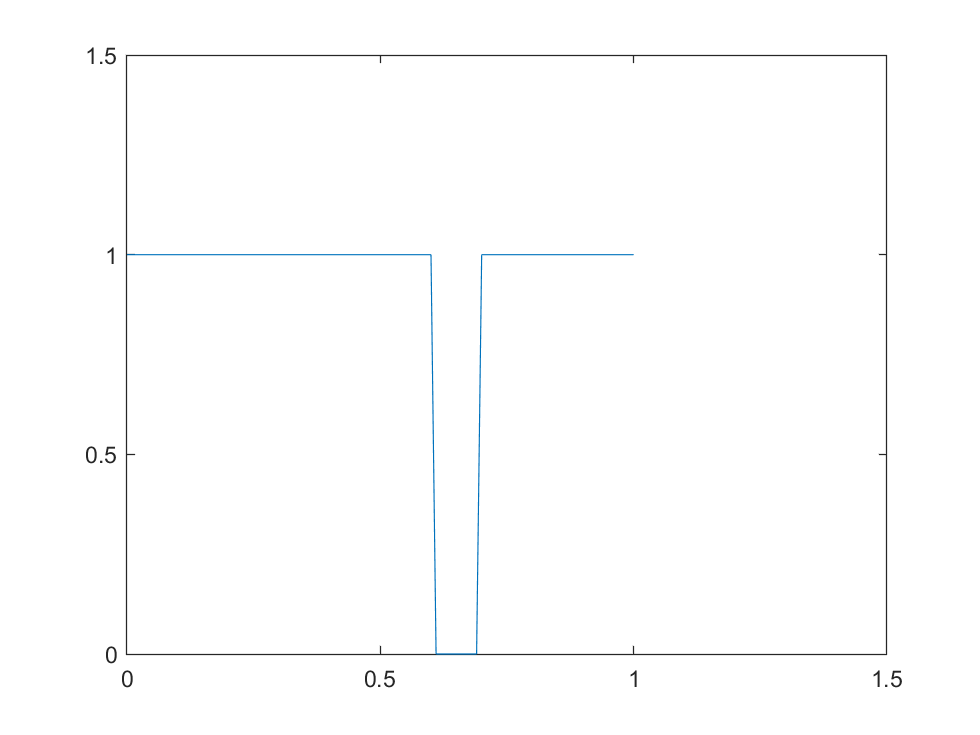


figure(5);
plot([0:0.01:1],ifft(fft(double(y([0:0.01:1])))));
axis([0 1.5 0 1.5]);

# part 2 Kyle:

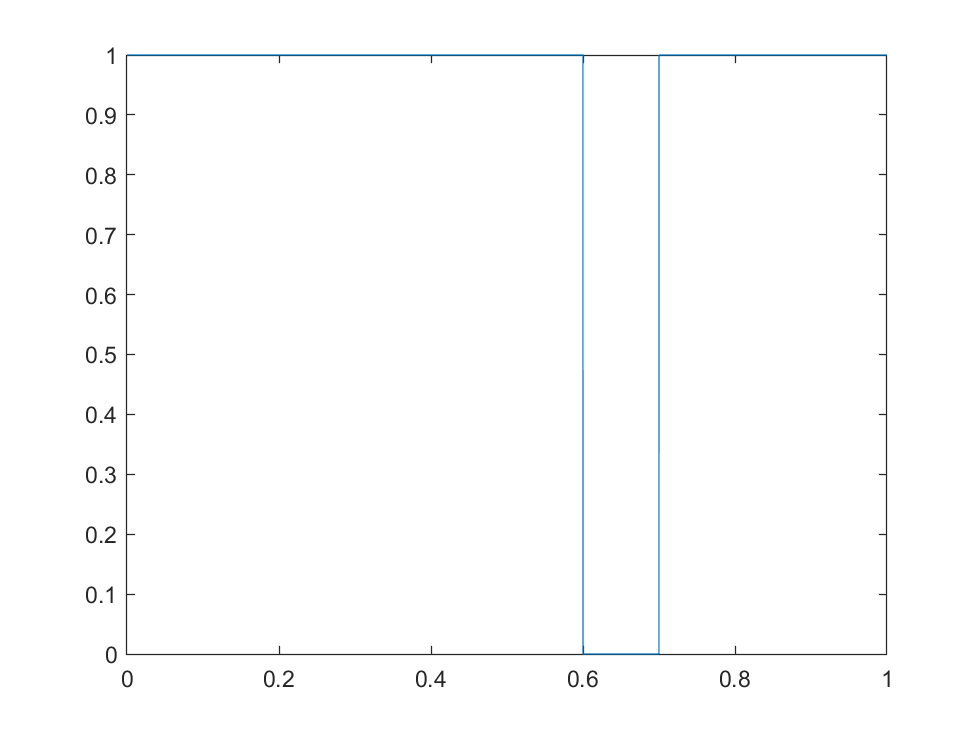

clf;
syms x;
fplot(heaviside([x-0.7]) - heaviside([x-0.6]) + heaviside([x]) , [0,1])


%Steps in millisecond
t = 0:0.01:1-0.01;
fs = 100;
sf = heaviside(t-0.7) - heaviside(t-0.6) + heaviside(t);
% sf = sinc(2*pi*10*t)
% plot(sf)
X = fft(sf)

X =   90.0000 + 0.0000i   6.0297 - 7.7735i   2.3280 + 9.0670i  -7.8896 - 3.4141i   6.6496 - 3.6557i  -1.0000 + 6.3138i  -3.4744 - 3.6999i   3.6922 - 0.3490i  -1.2664 + 1.9956i  -0.3752 - 1.0421i   0.0000 + 0.0000i   0.7545 - 0.5128i  -0.1003 + 1.5936i  -1.5280 - 1.3471i   2.1941 - 0.4186i  -1.0000 + 1.9626i  -0.8406 - 1.7863i   1.5510 + 0.3467i  -0.8452 + 0.6992i  -0.0173 - 0.5495i   0.0000 + 0.0000i   0.4842 - 0.1407i  -0.3395 + 0.8574i  -0.6227 - 1.0530i   1.3784 + 0.1741i  -1.0000 + 1.0000i  -0.1635 - 1.2944i   0.9283 + 0.5490i  -0.7093 + 0.2808i   0.1091 - 0.3756i   0.0000 + 0.0000i   0.3734 + 0.0117i  -0.4437 + 0.5364i  -0.2050 - 0.9173i   0.9820 + 0.4621i  -1.0000 + 0.5095i   0.1970 - 1.0325i   0.5830 + 0.6612i  -0.6309 + 0.0397i   0.1846 - 0.2716i   0.0000 + 0.0000i   0.3028 + 0.1090i  -0.5124 + 0.3252i   0.0780 - 0.8253i   0.7058 + 0.6628i  -1.0000 + 0.1584i   0.4618 - 0.8400i   0.3227 + 0.7458i  -0.5704 - 0.1465i   0.2443 - 0.1895i


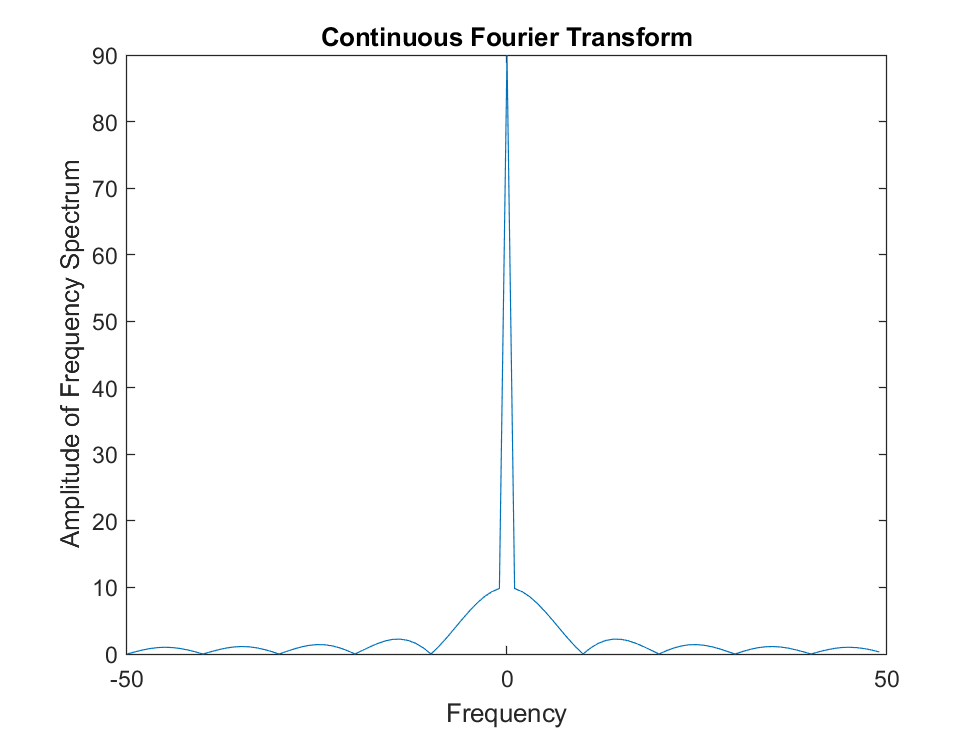

L = length(t); 

% f = (0:length(X)-1)*L/length(X);
% plot(f,abs(X))

X_shift = fftshift(X);
dF = fs/L;
f = -fs/2:dF:fs/2-dF;

Y = abs(X_shift);

plot(f,Y)
title('Continuous Fourier Transform')
ylabel('Amplitude of Frequency Spectrum')
xlabel('Frequency')

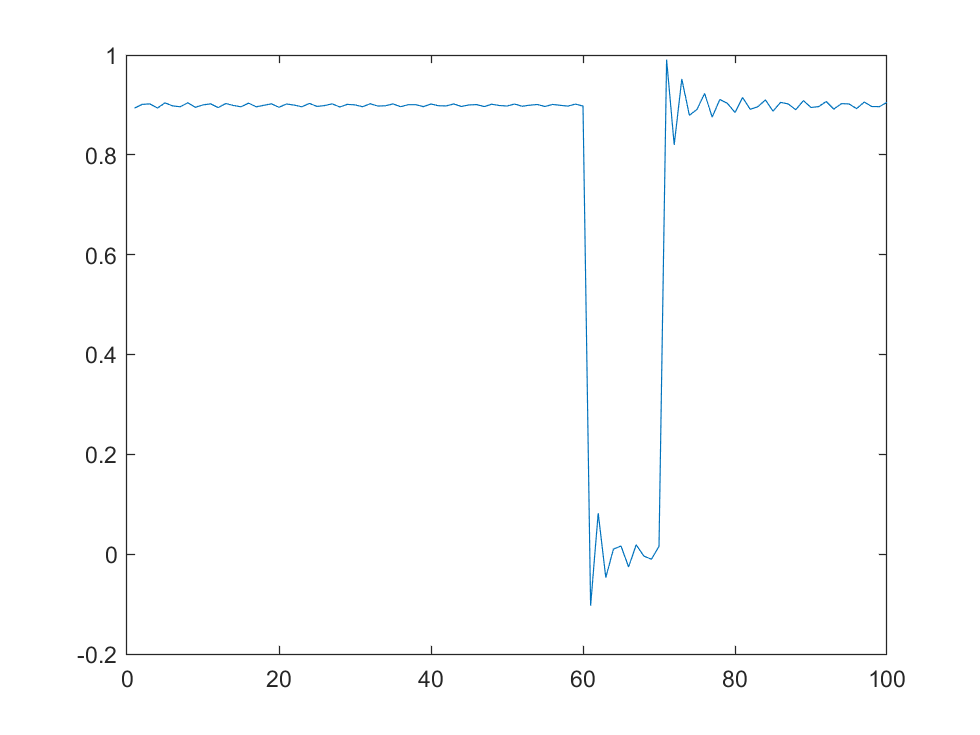



S = sinc(2*pi*20*t);
Xmag = abs(X);
Xphase = angle(X);
Smag = abs(fft(S));
Sphase = angle(fft(S));

fs2 = fftshift(fft(S));
inverse_fft = ifft(fft(S).*X);
plot(inverse_fft)

%Look at the graph at 10 Hz
% Minimum sampling frequency has to be 10.

# Part 3 Mike J:

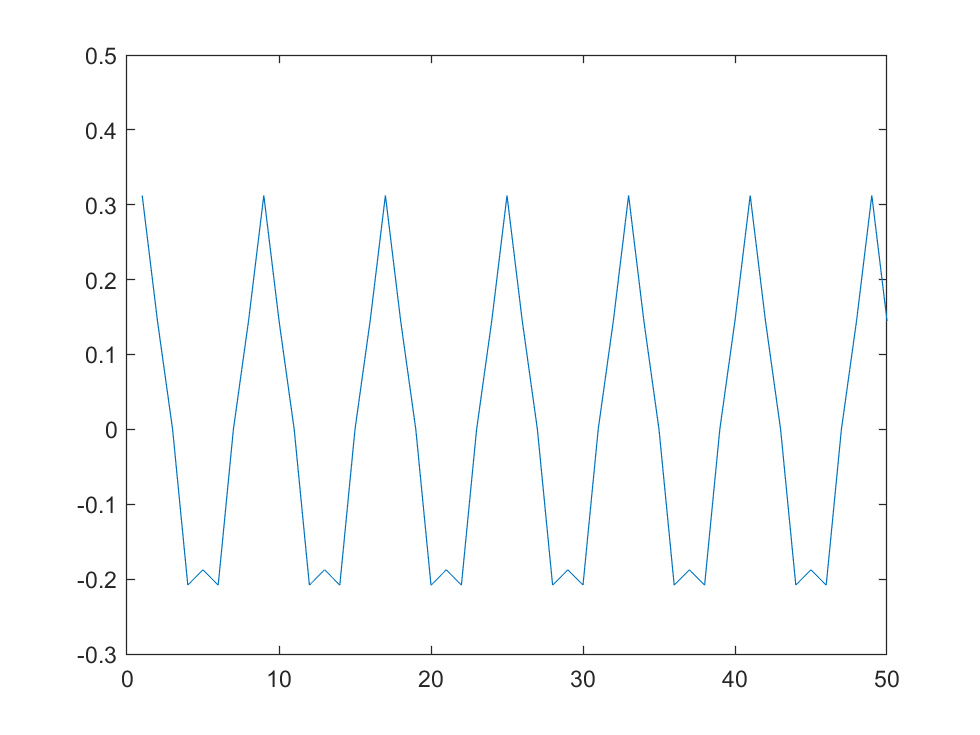

%Part 3a
snr=20; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';

A_c = 0.25; 
A_m = 0.25; 
f_m = 5000;
f_c = 25000;

s = A_c*[1+A_m.*cos(2*pi*f_m*t)].*(cos(2*pi*f_c*t));

%Compute signal variance 
var_s = cov(s);

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); %sound(n);


%Add signal to noise and generate message 
m=s+n; %sound(m); 

plot(s)
axis([0 50 -.3 .5])

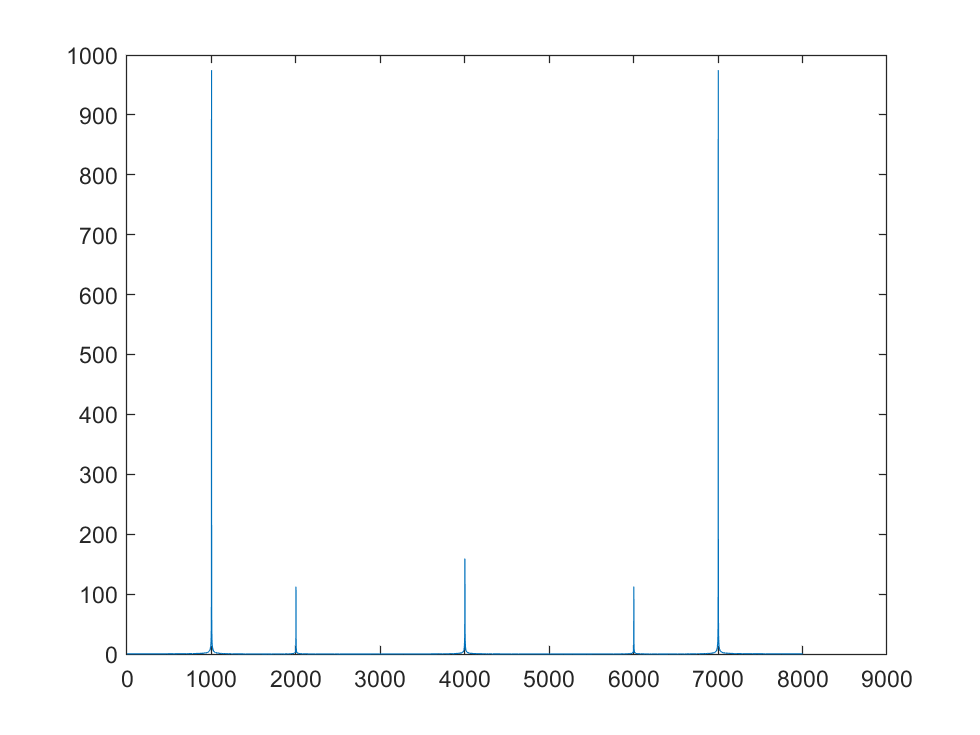

plot(abs(fft(s)))

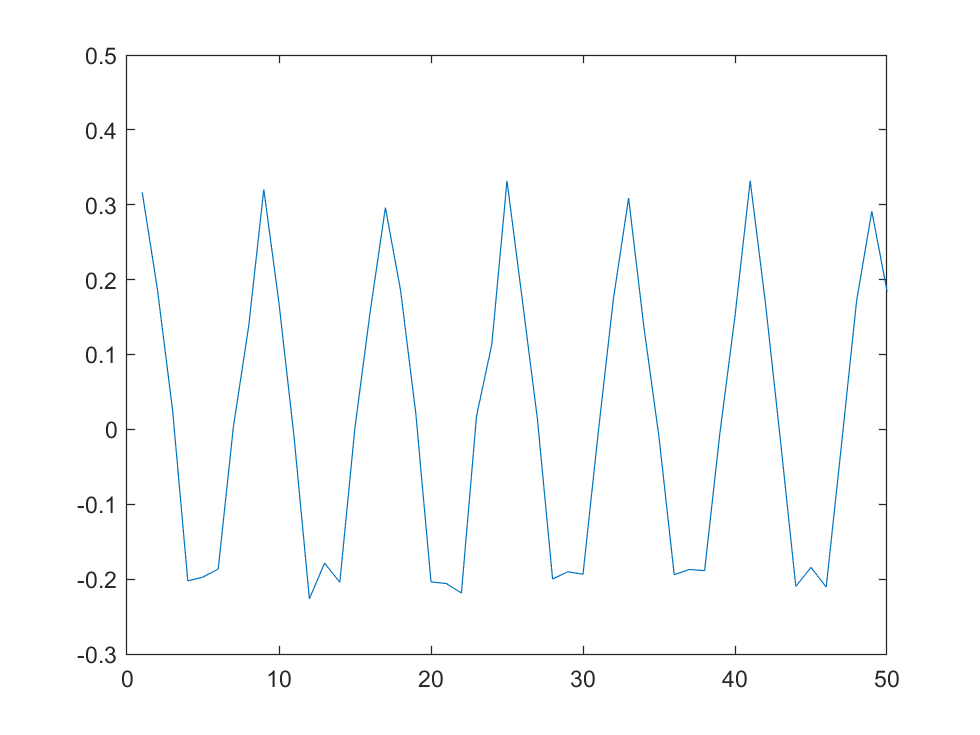


plot(m)
axis([0 50 -.3 .5])

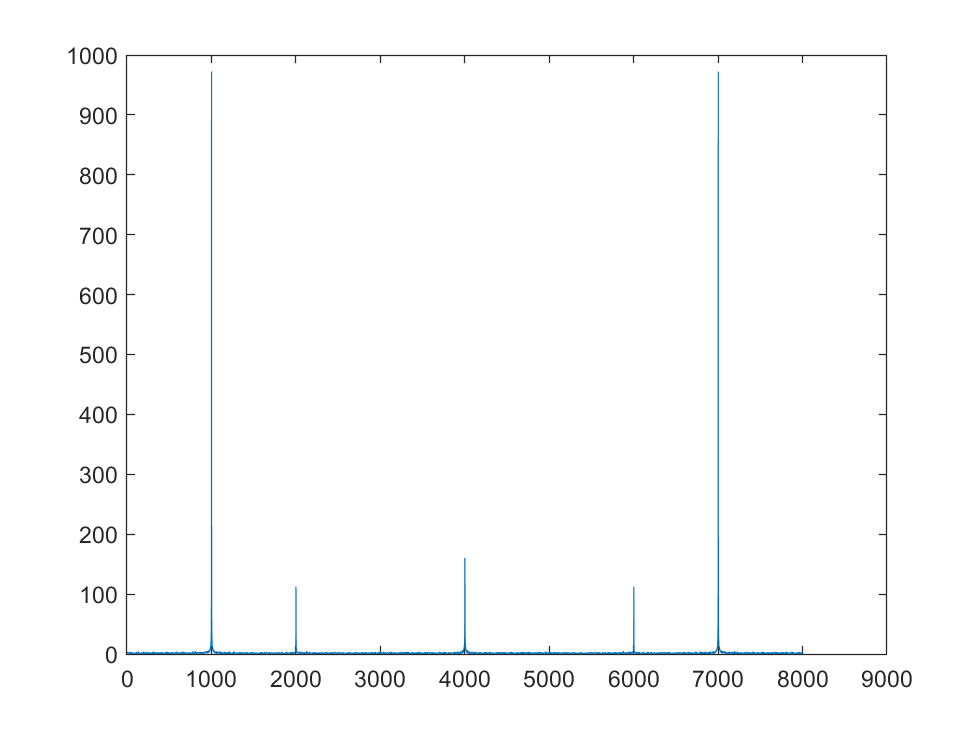

plot(abs(fft(m)))

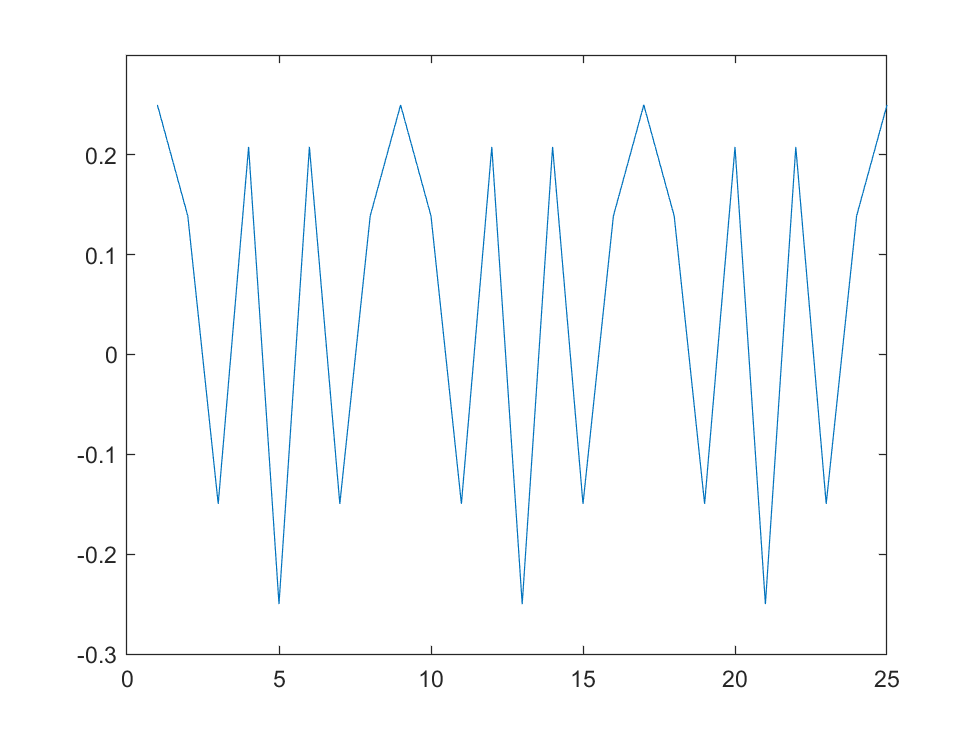



%Part 3b
clf;
snr=20; 

%Generate Asharp signal
t=[0:1/8e3:1.0]';

A_c = 0.25; 
A_m = 0.25; 
f_m = 5000;
f_c = 25000;
b_f = 10;

s = A_c.*cos(2.*pi.*f_c.*t+b_f.*A_m.*sin(2.*pi.*f_m.*t));

%Compute signal variance 
var_s = cov(s);

%Calculate required noise variance 
var_noise=var_s/(10^(snr/10)); 

%Generate noise 
n=sqrt(var_noise)*randn(length(s),1); %sound(n);

%Add signal to noise and generate message 
m=s+n; %sound(m); 

plot(s)
axis([0 25 -.3 .3])

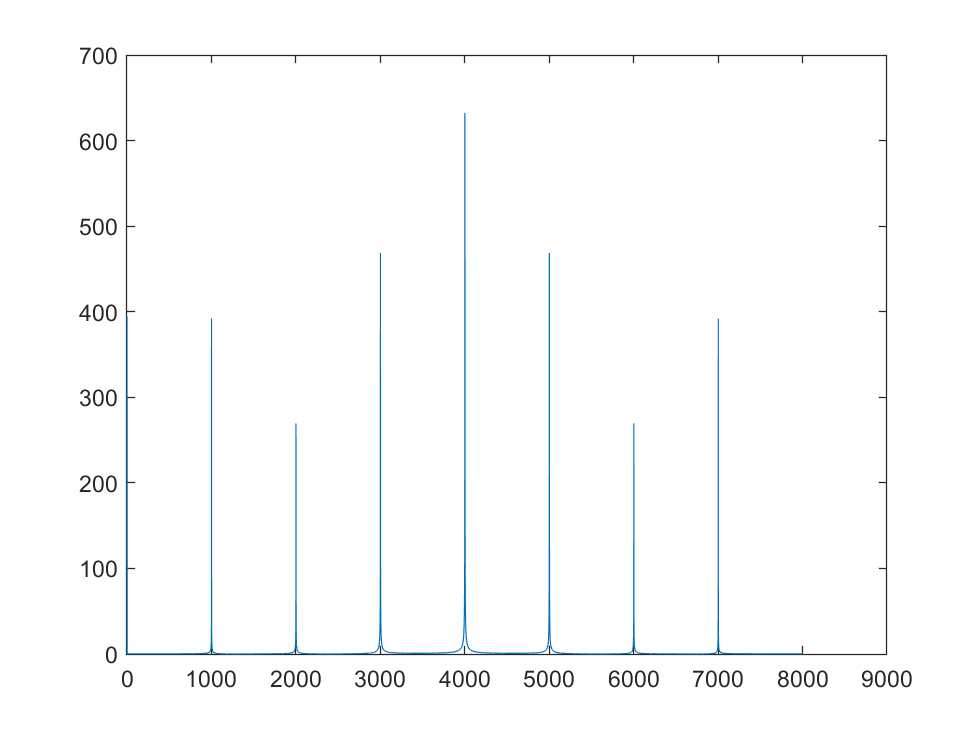

plot(abs(fft(s)))

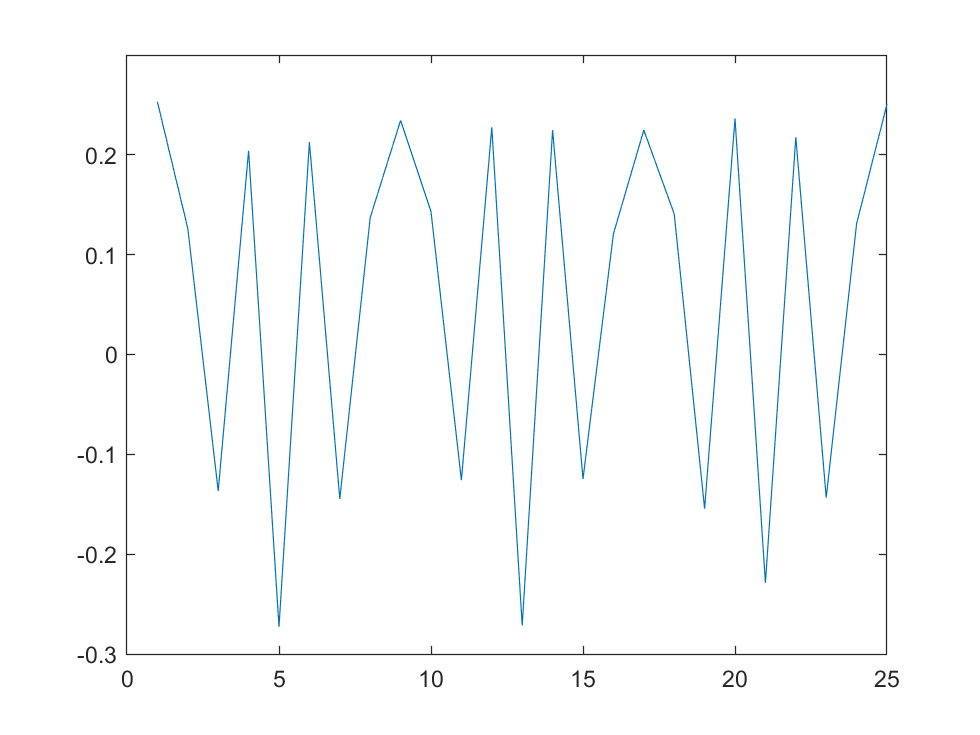


plot(m)
axis([0 25 -.3 .3])

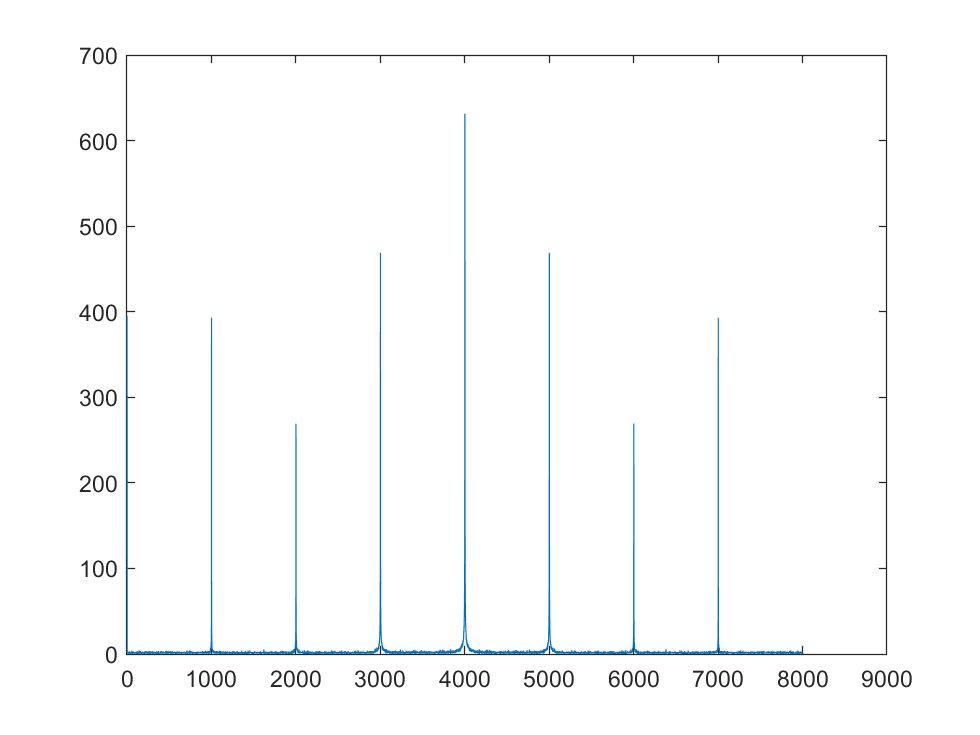

plot(abs(fft(m)))

# Part 4: Dawson                                             

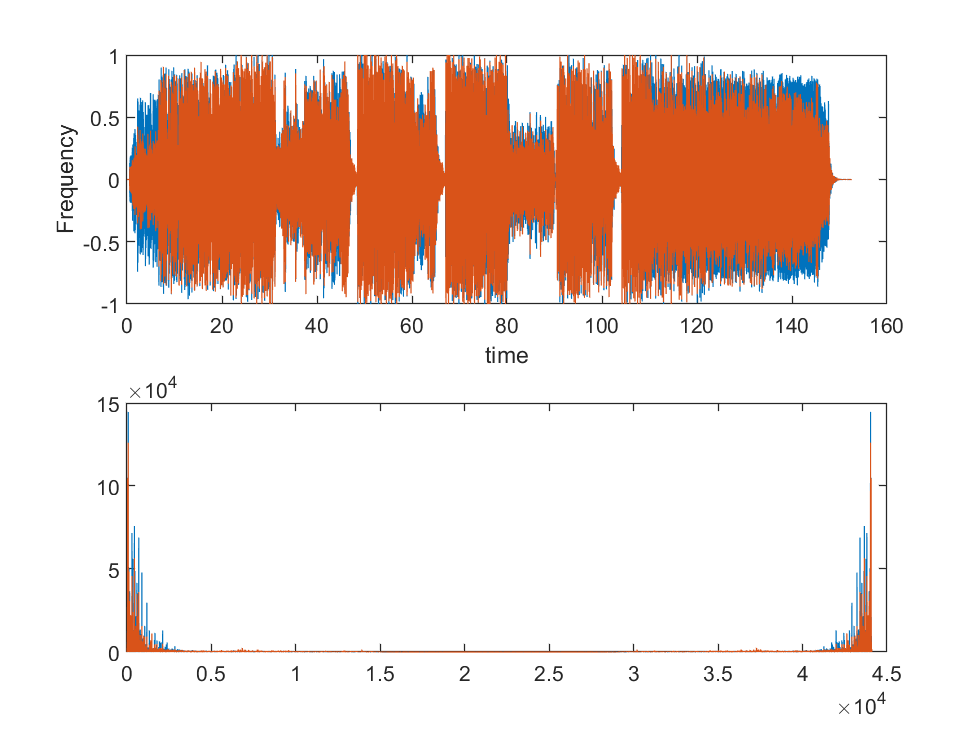

[data, fs] = audioread('Callen Lane - Carol Of The Bells.wav');

t=0:1/fs:(length(data)-1)/fs;
subplot(2,1,1);
plot(t,data)
xlabel('time')
ylabel('Frequency')

n = length(data)-1;
f = 0:fs/n:fs;
fft = abs(fft(data));
subplot(2,1,2);
plot(f,fft)


clear sound;